program

% clc;
% clear;
% 
% iteracje_sym_bezprzes = zeros(30);
% iteracje_sym_przes = zeros(30);
% cond_sym = zeros(30);
% cond_niesym = zeros(30);
% iteracje_niesym_przes = zeros(30);
% 
% for rozmiar = [5 10 20]
%     for i = 1:30
%         A = macierz_symetryczna(rozmiar);
%         [B iteracje_sym_bezprzes(i,rozmiar)] = qr_bezprzesuniec(A);
%         [B iteracje_sym_przes( i,rozmiar)] = qr_przesuniecia(A);
%         cond_sym(i,rozmiar) = cond(A);
%         %eig(A);
%         A = macierz_niesymetryczna(rozmiar);
%         [B iteracje_niesym_przes(i,rozmiar)] = qr_przesuniecia(A);
%         cond_niesym(i,rozmiar) = cond(A);
%     end
% end

statystyki i czyszczenie danych

% for rozmiar = [5 10 20]
%     rozmiar
%     sr_sym_bezprzes = iteracje_sym_bezprzes(:,rozmiar)
%     sr_sym_przes = iteracje_sym_przes(:,rozmiar)
%     sr_niesym_przes = iteracje_niesym_przes(:,rozmiar)
%     for i = 1:3
%         [wart indx] = max(cond_sym(:,rozmiar));
%         iteracje_sym_bezprzes(indx,rozmiar) = 0;
%         iteracje_sym_przes(indx,rozmiar) = 0;
%         cond_sym(indx,rozmiar) = 0;
%         
%         [wart indx] = max(cond_niesym(:,rozmiar));
%         iteracje_niesym_przes(indx,rozmiar) = 0;
%         cond_niesym(indx,rozmiar) = 0;
%     end
% end

for rozmiar = [5 10 20]
    rozmiar
    sr_sym_bezprzes = mean(iteracje_sym_bezprzes(:,rozmiar))
    sr_sym_przes = mean(iteracje_sym_przes(:,rozmiar))
    sr_niesym_przes = mean(iteracje_niesym_przes(:,rozmiar))
end

rozmiar = 5

sr_sym_bezprzes = 105.7667

sr_sym_przes = 7.1667

sr_niesym_przes = 10.6333

rozmiar = 10

sr_sym_bezprzes = 175.8667

sr_sym_przes = 14.3000

sr_niesym_przes = 23.8000

rozmiar = 20

sr_sym_bezprzes = 180.9000

sr_sym_przes = 27.9667

sr_niesym_przes = 54.8333

wykresy

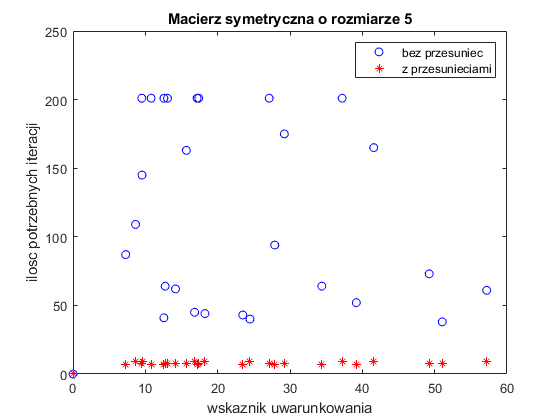

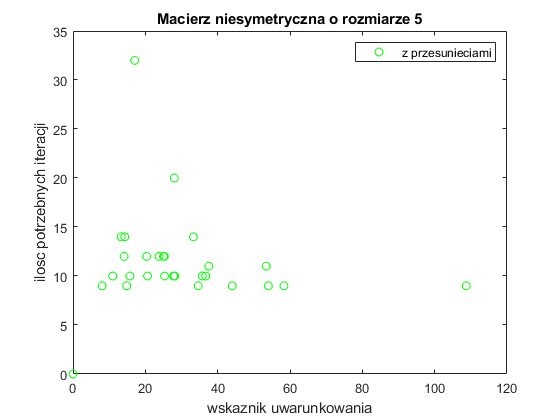

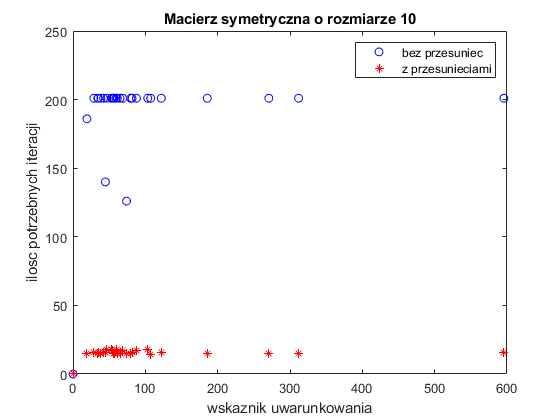

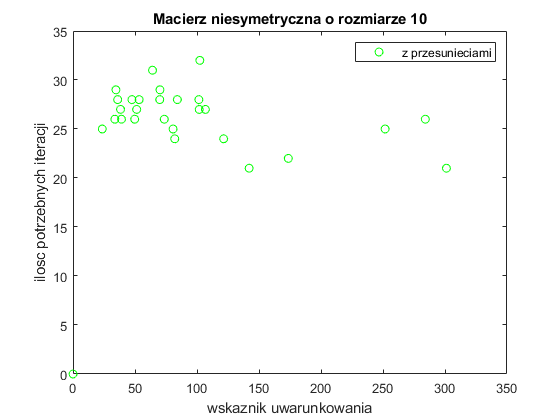

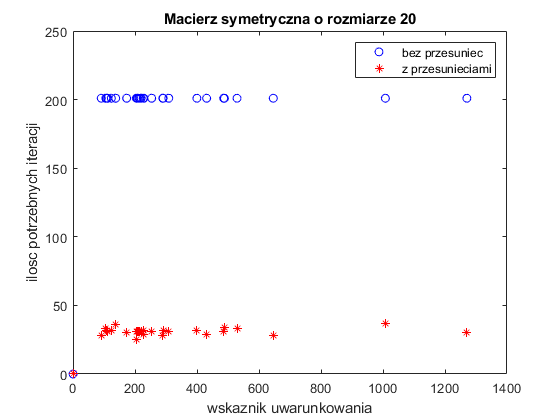

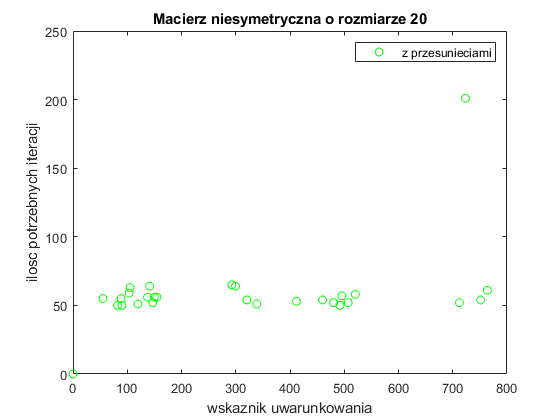

for rozmiar = [5 10 20]
    figure
    plot(cond_sym(:,rozmiar),iteracje_sym_bezprzes(:,rozmiar),'bo', cond_sym(:,rozmiar), iteracje_sym_przes(:,rozmiar), 'r*');
    title(['Macierz symetryczna o rozmiarze ' num2str(rozmiar)])
    xlabel('wskaznik uwarunkowania') 
    ylabel('ilosc potrzebnych iteracji')
    legend({'bez przesuniec','z przesunieciami'},'Location','northeast');
    figure
    plot(cond_niesym(:,rozmiar),iteracje_niesym_przes(:,rozmiar),'go');
    title(['Macierz niesymetryczna o rozmiarze ' num2str(rozmiar)])
    xlabel('wskaznik uwarunkowania') 
    ylabel('ilosc potrzebnych iteracji')
    legend({'z przesunieciami'},'Location','northeast');
end

**funkcje pomocnicze**

rozklad QR

function [Q R] = qr_rozklad(A)
     [r_wiersze r_kolumny] = size(A);
     Q = zeros(r_wiersze);
     if r_wiersze > r_kolumny
        R = eye(r_wiersze);
        Q = eye(r_wiersze);
     else
        R = eye(r_kolumny);
        Q = eye(r_wiersze);
     end
    %Gram-Schmidt
     for i = 1:r_kolumny
         Q(:,i) = A(:,i);
         for j = 1:(i-1)
             R(j,i) = mydot(Q(:,j),A(:,i))/mydot(Q(:,j),Q(:,j));
             Q(:,i) = Q(:,i) - R(j,i)*Q(:,j);
         end
     end
     Q = Q(1:r_wiersze,1:r_kolumny);
     %normalizacja
     N = zeros(r_wiersze);
     for i = 1:r_kolumny
         N(i,i) = norm(Q(:,i));
         Q(:,i) = Q(:,i)/N(i,i);
     end
     R = N*R;
     
     if r_wiersze > r_kolumny
        R = R(1:r_kolumny,1:r_kolumny);
     else
        R = R(1:r_wiersze,1:r_wiersze);
     end
end


algorytm obliczania wartosci wlasnych metoda QR bez przesuniec

function [wart_wlasne i] = qr_bezprzesuniec(A)
    i = 0;
    while tolerancja(A) > 0.00001 & i < 200+1
        [Q R] = qr_rozklad(A);
        A = R * Q;
        i = i+1;
    end
    wart_wlasne = wektor(A);
end

 algorytm obliczania wartosci wlasnych metoda QR z przesunieciami

function [wart_wlasne i] = qr_przesuniecia(A)
    rozmiar = size(A,1);
    i = 0;
    wart_wlasne = zeros(rozmiar);
    wart_wlasne = wart_wlasne(:,1);
    for j = rozmiar:-1:2
        while max(abs(A(j,1:j-1))) > 0.00001 & i < 200+1
            mala_macierz = A(j-1:j,j-1:j);                            % macierz 2x2,
            [x1 x2] = pierw_f_kwadratowej(mala_macierz);
            przesuniecie = blizsza_liczba(mala_macierz(2,2), x1, x2); % z ktorej wyznaczana jest najlepsza wart. wlasna
            A = A - eye(j)*przesuniecie;
            [Q R] = qr_rozklad(A);
            A = R * Q + eye(j)*przesuniecie;
            i = i+1;
        end
        wart_wlasne(j) = A(j,j);
        if j > 2
            A = A(1:j-1,1:j-1);             %deflacja
        else
            wart_wlasne(1) = A(1,1);
        end
    end
end

wyznaczanie pierw f. kwadratowej

function [x1 x2] = pierw_f_kwadratowej(mala_macierz)
    a = 1;
    b = -(mala_macierz(1,1)+mala_macierz(2,2));
    c = (mala_macierz(1,1)*mala_macierz(2,2))-(mala_macierz(2,1)*mala_macierz(1,2));
    
    x1 = (-b + sqrt(b*b - 4*a*c))/(2*a);
    x2 = (-b - sqrt(b*b - 4*a*c))/(2*a);
    if abs(x2) > abs(x1)
        x1 = x2;
    end
   %drugi pierwiastek ze wzorów Viete'a
    x2 = ((-b)/a) - x1;
end

wybor pierwiastka blizszego d(n,n)

function x = blizsza_liczba(wlasciwa, x1, x2)
    if abs(wlasciwa-x1) < abs(wlasciwa-x2)
        x = x1;
    else
        x = x2;
    end
end

autorska implementacja matlabowej funkcji dot()

function md = mydot(A,B)
    rozmiar = size(A);
    md = 0;
    for i = 1:rozmiar
        md = md + A(i)*B(i);
    end
end

funkcja wektoryzujaca macierz diagonalna

function w = wektor(A)
    rozmiar = size(A);
    for i = 1:rozmiar
        w(i,1) = A(i,i);
    end
end

sprawdzenie tolerancji

function tol = tolerancja(A)
    rozmiar = size(A);
    A = abs(A);
    tol = 0;
    if rozmiar > 2
        for i = 1:rozmiar
            if max(A(i,i+1:end)) > tol
                tol = max(A(i,i+1:end));
            end
            if max(A(i,1:i-1)) > tol
                tol = max(A(i,1:i-1));
            end
        end
    else
        tol = 0;
    end
end

tworzenie macierzy symetrycznej o zadanym rozmiarze

function mac_sym = macierz_symetryczna(rozmiar)
    mac_sym = randi([0 50],rozmiar,rozmiar);
    mac_sym = mac_sym + mac_sym';
end

tworzenie macierzy niesymetrycznej o zadanym rozmiarze

function mac_nsym = macierz_niesymetryczna(rozmiar)
    mac_nsym = randi([0 100],rozmiar,rozmiar);
end

norma residuum

function nr = norma_residuum(wspolczynniki, x, rozw)
    residuum = wspolczynniki*x - rozw;
    nr = norm(residuum);
end